[t_list, freq_list] = process_fidget_spinner_video("fidgetspinnervideo.mov", 0)

Video processing complete: 0%
Video processing complete: 1%
Video processing complete: 2%
Video processing complete: 3%
Video processing complete: 4%
Video processing complete: 5%
Video processing complete: 6%
Video processing complete: 7%
Video processing complete: 8%
Video processing complete: 9%
Video processing complete: 10%
Video processing complete: 11%
Video processing complete: 12%
Video processing complete: 13%
Video processing complete: 14%
Video processing complete: 15%
Video processing complete: 16%
Video processing complete: 17%
Video processing complete: 18%
Video processing complete: 19%
Video processing complete: 20%
Video processing complete: 21%
Video processing complete: 22%
Video processing complete: 23%
Video processing complete: 24%
Video processing complete: 25%
Video processing complete: 26%
Video processing complete: 27%
Video processing complete: 28%
Video processing complete: 29%
Video processing complete: 30%
Video processing complete: 31%
Video processing c

t_list =          0    1.0756    2.1512    3.2434    4.3774    5.5614    6.7454    7.9377    9.1634   10.4474   11.8231   13.2656   14.7831   16.4757   18.3517   20.4695   22.8875   25.5890   28.4989   31.4506   35.8530


freq_list =   125.5949  119.3151  113.0354  106.7556  100.4759   94.1962   87.9164   81.6367   75.3569   69.0772   62.7974   56.5177   50.2380   43.9582   37.6785   31.3987   25.1190   18.8392   12.5595    6.2797         0


fname_save = "mydata.mat";
save(fname_save, "t_list", "freq_list")

S = load("mydata.mat", "t_list", "freq_list")

S = struct with fields:
       t_list: [0 1.0756 2.1512 3.2434 4.3774 5.5614 6.7454 7.9377 9.1634 10.4474 11.8231 13.2656 14.7831 16.4757 18.3517 20.4695 22.8875 25.5890 28.4989 31.4506 35.8530]
    freq_list: [125.5949 119.3151 113.0354 106.7556 100.4759 94.1962 87.9164 81.6367 75.3569 69.0772 62.7974 56.5177 50.2380 43.9582 37.6785 31.3987 25.1190 18.8392 12.5595 6.2797 0]


t_list = S.t_list

t_list =          0    1.0756    2.1512    3.2434    4.3774    5.5614    6.7454    7.9377    9.1634   10.4474   11.8231   13.2656   14.7831   16.4757   18.3517   20.4695   22.8875   25.5890   28.4989   31.4506   35.8530


freq_list = S.freq_list

freq_list =   125.5949  119.3151  113.0354  106.7556  100.4759   94.1962   87.9164   81.6367   75.3569   69.0772   62.7974   56.5177   50.2380   43.9582   37.6785   31.3987   25.1190   18.8392   12.5595    6.2797         0



freq_list = freq_list ./ 3

freq_list =    41.8650   39.7717   37.6785   35.5852   33.4920   31.3987   29.3055   27.2122   25.1190   23.0257   20.9325   18.8392   16.7460   14.6527   12.5595   10.4662    8.3730    6.2797    4.1865    2.0932         0


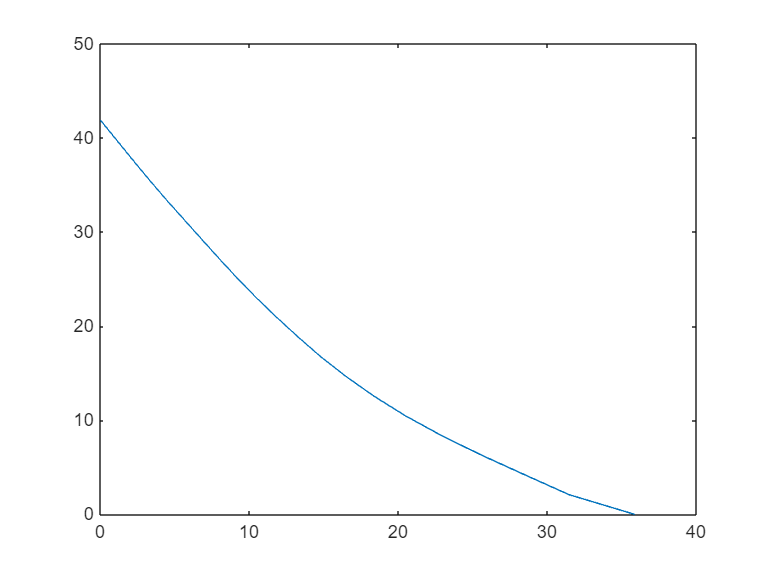

figure;
plot(t_list, freq_list)


t_length = length(freq_list)-1

t_length = 20


freq_midpoints = zeros(1, t_length-1);
for index = 1:t_length
    freq_midpoints(index) = (freq_list(index)+freq_list(index+1))/2;
end
freq_midpoints

freq_midpoints =    40.8183   38.7251   36.6318   34.5386   32.4453   30.3521   28.2588   26.1656   24.0724   21.9791   19.8859   17.7926   15.6994   13.6061   11.5129    9.4196    7.3264    5.2331    3.1399    1.0466



angular_acc = zeros(1, t_length);
for index = 1:t_length
    angular_acc(index) = (freq_list(index+1)-freq_list(index)) / (t_list(index+1)-t_list(index));
end
angular_acc

angular_acc =    -1.9461   -1.9461   -1.9164   -1.8460   -1.7680   -1.7680   -1.7556   -1.7078   -1.6302   -1.5215   -1.4512   -1.3794   -1.2367   -1.1158   -0.9884   -0.8657   -0.7749   -0.7193   -0.7092   -0.4755



p = polyfit(freq_midpoints, angular_acc, 2)

p =     0.0006   -0.0646   -0.3964


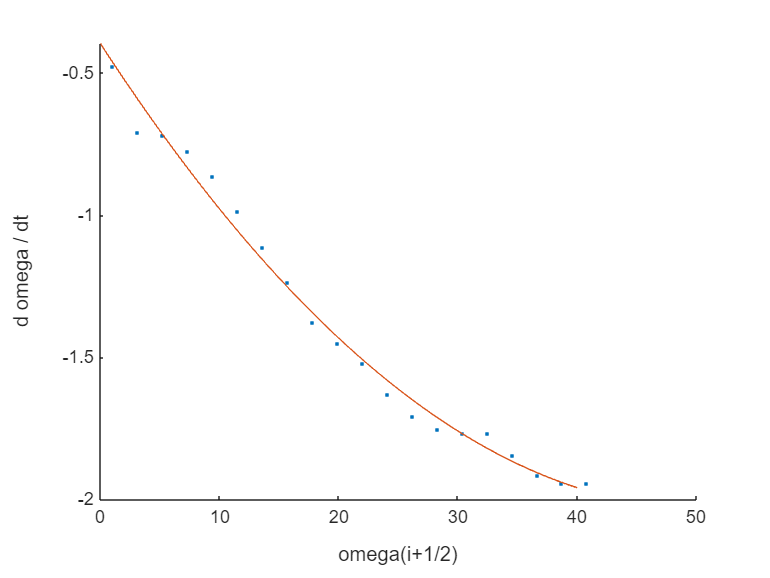


figure;
scatter(freq_midpoints, angular_acc, "."); hold on;
xlabel("omega(i+1/2)")
ylabel("d omega / dt")
omega = linspace(0,40,100);
plot(omega, p(1)*omega.^2 + p(2).*omega + p(3));



f = @(t_in,omega_in) p(1)*omega_in^2 + p(2)*omega_in + p(3);
[ode45_t_list, ode45_freq_list] = ode45(f, [0, 40], freq_list(1))

ode45_t_list =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


ode45_freq_list =    41.8650
   39.8946
   37.9510
   36.0385
   34.1612
   32.3229
   30.5269
   28.7763
   27.0738
   25.4216


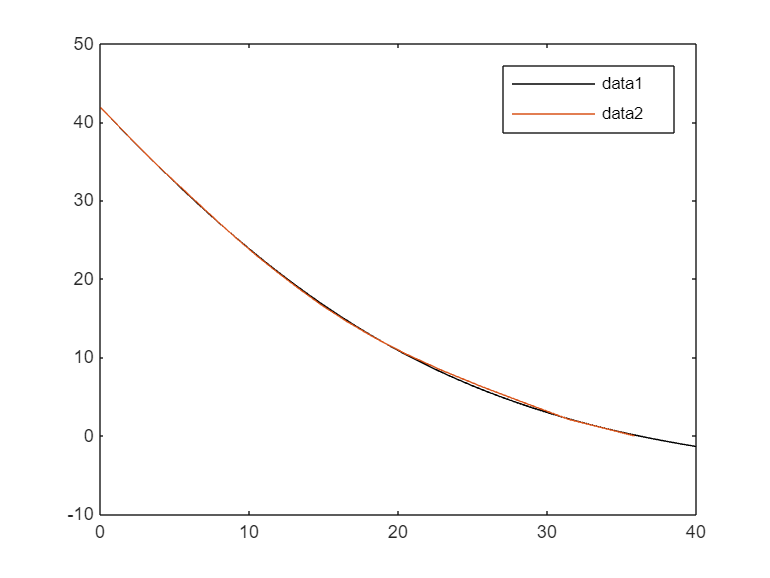

figure;
plot(ode45_t_list, ode45_freq_list, "k-"); hold on;
plot(t_list, freq_list)
legend()

[t,omega] = meshgrid(0:2:40, 0:2:40)

t =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40
     0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    3

omega =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8
    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12
    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14 


dOmega = p(1)*omega.^2 + p(2)*omega + p(3);
dT = ones(size(dOmega));

figure();
quiver(t, omega, dT, dOmega); hold on;
axis([0,40,0,40])

init_conditions = [40, 20, 10];
for init = init_conditions
    [ode45_t_list, ode45_freq_list] = ode45(f, [0, 40], init)
    plot(ode45_t_list, ode45_freq_list)
end

ode45_t_list =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


ode45_freq_list =    40.0000
   38.0548
   36.1406
   34.2612
   32.4207
   30.6224
   28.8693
   27.1641
   25.5092
   23.9064


ode45_t_list =          0
    0.7010
    1.4020
    2.1031
    2.8041
    3.8041
    4.8041
    5.8041
    6.8041
    7.8041


ode45_freq_list =    20.0000
   19.0090
   18.0457
   17.1100
   16.2019
   14.9542
   13.7620
   12.6245
   11.5409
   10.5099


ode45_t_list =          0
    0.5133
    1.0266
    1.5399
    2.0532
    3.0532
    4.0532
    5.0532
    6.0532
    7.0532


ode45_freq_list =    10.0000
    9.5043
    9.0217
    8.5521
    8.0953
    7.2412
    6.4331
    5.6693
    4.9481
    4.2677


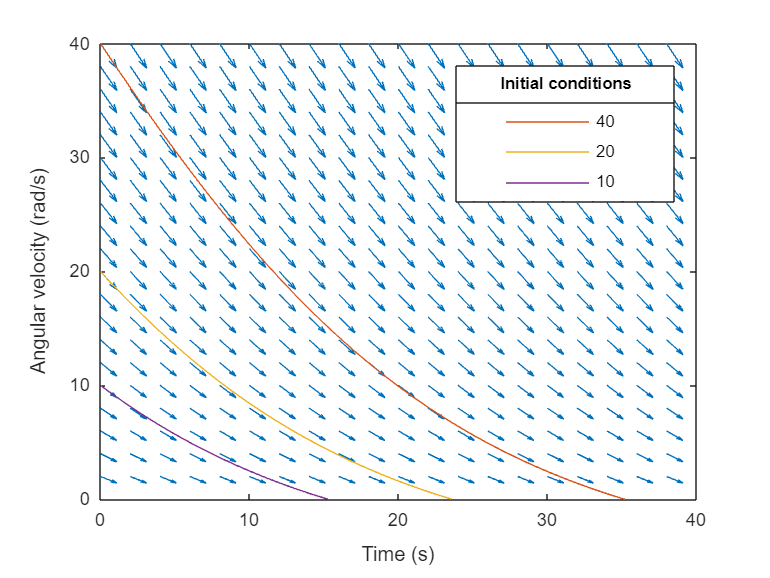

lgd = legend("", "40", "20", "10");
title(lgd,'Initial conditions');
xlabel("Time (s)");
ylabel("Angular velocity (rad/s)");